# MPO 651 - Assignment #1 Spring 2020 (due to 3/5)              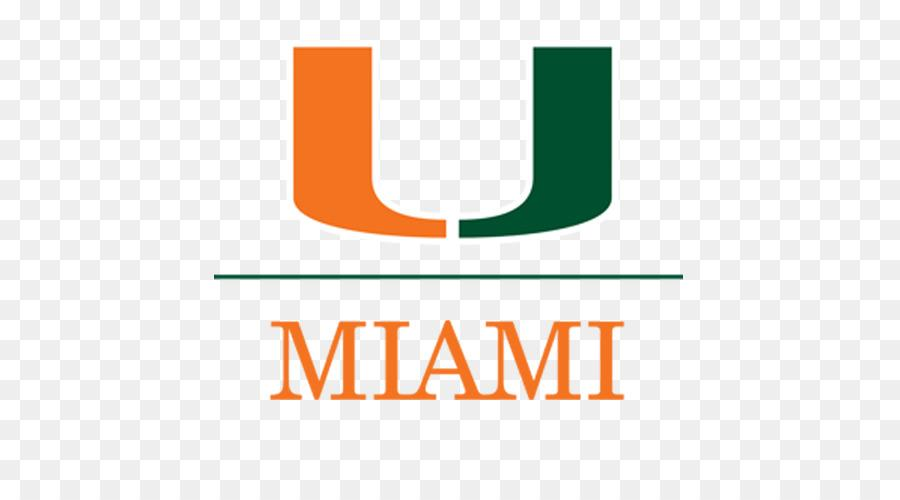

## Ivenis Pita

#### 1- Loading and organizing data

clear variables
close all
clc

%% var definition
mainfolder='/Users/ivenispita/Documents/UM_PhD/tide_gauge_data_BR/all_data';
foldernames={'10620_Santana';'30149_Madeira';'40141_Salvador';...
    '50140_Ilha_Fiscal';'50250_Cananeia';'60380_Rio_Grande'};
min_time=[];
max_time=[];
%% Load data
for k=1:size(foldernames,1)
    stn_folder=foldernames{k};
    load([mainfolder '/' stn_folder '/mat_' stn_folder(1:5) '.mat']);
    eval(['mat_' stn_folder(1:5) '(:,1)=julian(gregorian(mat_' stn_folder(1:5) '(:,1)));'])
    eval(['stn_' num2str(k) '=mat_' stn_folder(1:5) ';'])
    clear mat* title
    min_time=[min_time eval(['stn_' num2str(k) '(1,1);'])];%get initial time at each station
    max_time=[max_time eval(['stn_' num2str(k) '(end,1);'])];%get initial time at each station
end

%organizing time
time=min(min_time):1/24:max(max_time);
time=julian(gregorian(time));
stn_all=[];
for l=1:size(foldernames,1)
    stn_full=nan(size(time));
    eval(['stn_data=stn_' num2str(l) ';']);
    [ind1,loc1]=ismember(stn_data(:,1),time);
    [ind2,loc2]=ismember(time,stn_data(:,1));
    stn_full(ind2)=stn_data(ind1,2);
    stn_all=[stn_all stn_full];
end
stn_all=[stn_all time];

#### 2- Brief quality control

%Stn1
stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1)=stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1)-nanmean(stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1));

%Stn2
stn_all(:,2)=stn_all(:,2)-nanmean(stn_all(:,2));
% stn_all(407070:438360,6)=fillgaps(stn_all(407070:438360,6));
%Stn3
stn_all(490000:500000,3)=fillgaps(stn_all(490000:500000,3));
stn_all(:,3)=stn_all(:,3)-nanmean(stn_all(:,3));

%Stn4
stn_all(:,4)=stn_all(:,4)-nanmean(stn_all(:,4));

%Stn5
stn_all(300000:440000,5)=fillgaps(stn_all(300000:440000,5));
% stn_all(300000:440000,5)=fillgaps(stn_all(300000:440000,5));
stn_all(:,5)=stn_all(:,5)-nanmean(stn_all(:,5));

%Stn6
stn_all(stn_all(:,6)>=4,6)=nan;
stn_all(407070:438360,6)=fillgaps(stn_all(407070:438360,6));
stn_all(:,6)=stn_all(:,6)-nanmean(stn_all(:,6));

#### 3) Selecting periods

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
P1=stn_all(407065:438384,[2 5 6 7]);

#### 4) Ploting location of the stations

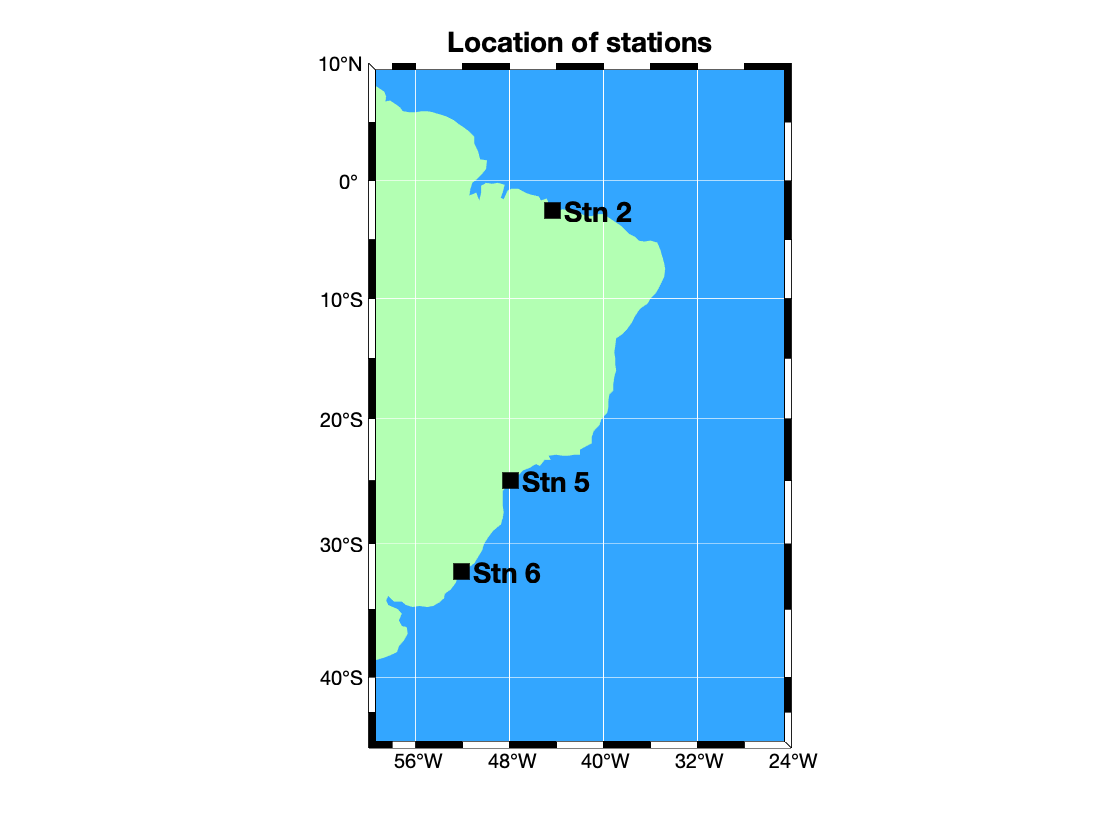

lat=[ -02.5650; -25.0167; -32.1383];
lon=[ -44.3783; -47.9250; -52.1033];
stations={'Stn 2','Stn 5','Stn 6'};
% lat=[ -00.0567; -02.5650; -12.9733; -22.8967; -25.0167; -32.1383];
% lon=[ -51.1817; -44.3783; -38.5167; -43.1667; -47.9250; -52.1033];
% stations={'Stn 1','Stn 2','Stn 3','Stn 4','Stn 5','Stn 6'};

m_proj('miller','lat',[-45 10],'lon',[-60 -24]);
m_coast('patch',[.7 1 .7],'edgecolor','none');
m_grid('box','fancy','linestyle','-','gridcolor','w','backcolor',[.2 .65 1]);
hold on
m_plot(lon,lat,'s','Markersize',10,'MarkerEdgeColor','k','MarkerFaceColor','k');
hold on
m_text(lon+1,lat,stations,'s','fontsize',14,'fontweight','bold');
title('Location of stations','fontsize',14,'fontweight','bold');

set(gcf,'color','w');   % Need to do this otherwise 'print' turns the lakes black

#### 5) Harmonical analysis

%P1 (stn 2, 5, 6)
stn=[2, 5, 6];
for m=1:size(P1,2)-1
    [tide_struc,xout]=t_tide(P1(:,m),'interval',1,'start_time',gregorian(P1(1,end)),'latitude',lat(stn(m)));
    P1(:,m)=P1(:,m)-xout;
    clear tide_struc xout
end

   number of standard constituents used: 68
   Points used: 31319 of 31320
   percent of var residual after lsqfit/var original:  0.75 %
   Greenwich phase computed with nodal corrections applied to amplitude 
 and phase relative to center time
   Using nonlinear bootstrapped error estimates
   Generating prediction with nodal corrections, SNR is 2.000000
   percent of var residual after synthesis/var original:  0.77 %
-----------------------------------
date: 05-Mar-2020
nobs = 31320,  ngood = 31319,  record length (days) = 1305.00
start time: 04-Aug-2000 03:00:00
rayleigh criterion = 1.0
Greenwich phase computed with nodal corrections applied to amplitude \n and phase relative to center time

x0= -0.00406, x trend= 0

var(x)= 2.4684   var(xp)= 2.4485   var(xres)= 0.019061
percent var predicted/var original= 99.2 %

     tidal amplitude and phase with 95% CI estimates

tide   freq       amp     amp_err    pha    pha_err     snr
*SA   0.0001141    0.0379    0.014   259.31    22.55     

#### 6) Plot data

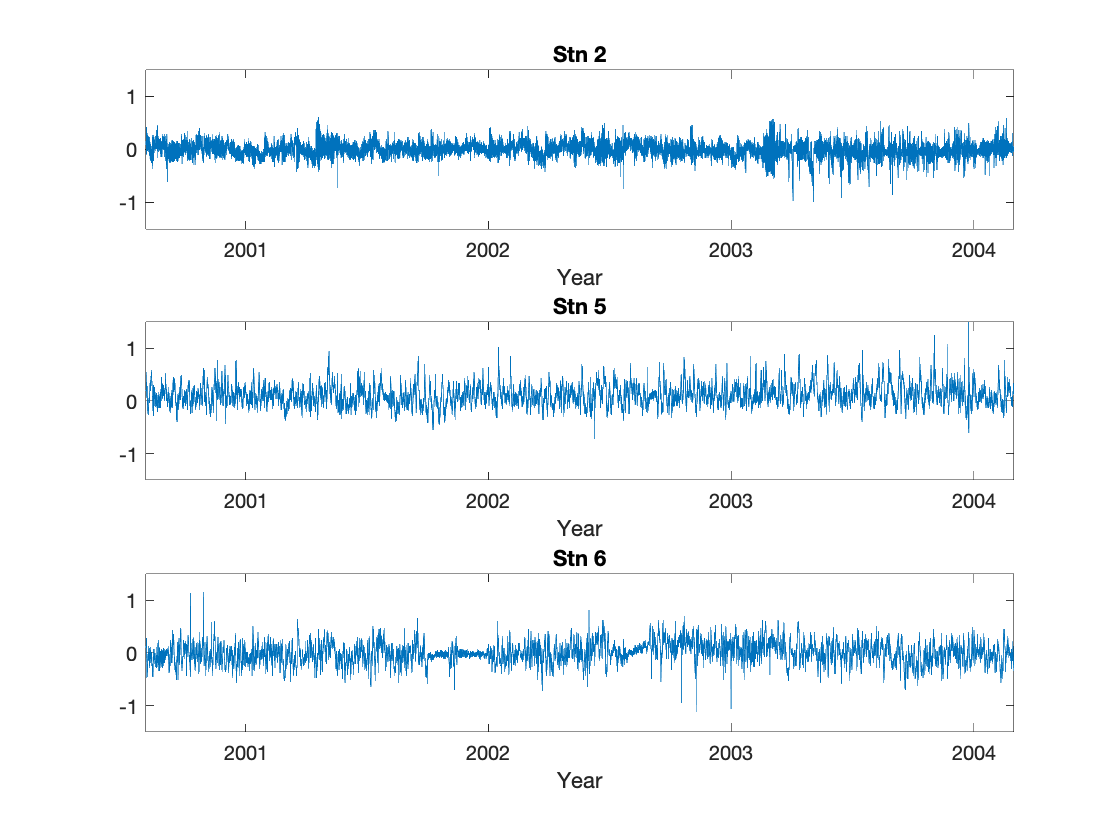

figure
subplot(311)
plot(P1(:,end),P1(:,1))
axis([P1(1,end) P1(end,end) -1.5 1.5])
% axis tight
gregaxy(P1(:,end),1)
title('Stn 2')
subplot(312)
plot(P1(:,end),P1(:,2))
axis([P1(1,end) P1(end,end) -1.5 1.5])
% axis tight
gregaxy(P1(:,end),1)
title('Stn 5')
subplot(313)
plot(P1(:,end),P1(:,3))
axis([P1(1,end) P1(end,end) -1.5 1.5])
% axis tight
gregaxy(P1(:,end),1)
title('Stn 6')

#### 7) Scattermatrix

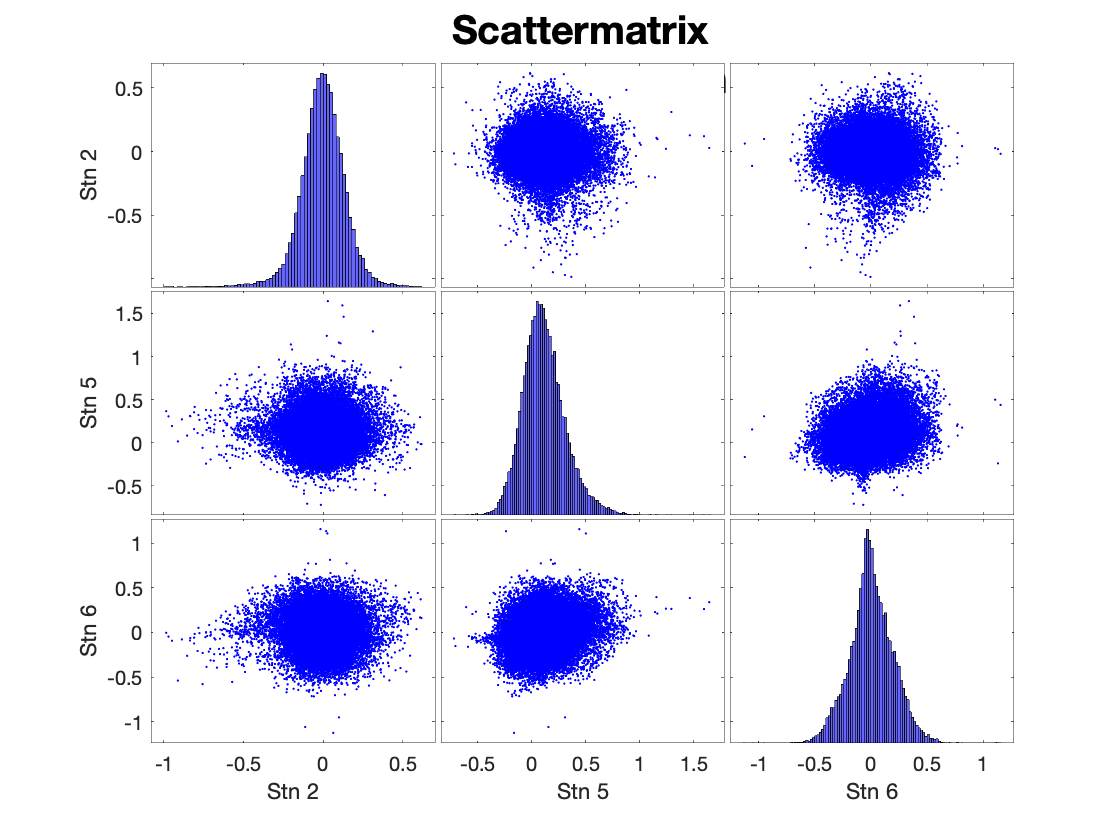

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
figure, 
xnames={'Stn 2','Stn 5','Stn 6'};
gplotmatrix(P1(:,1:end-1),[],[],'b',[],[],[],'grpbars',xnames)
title({'Scattermatrix';'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)

#### 8) Covariance Matrix

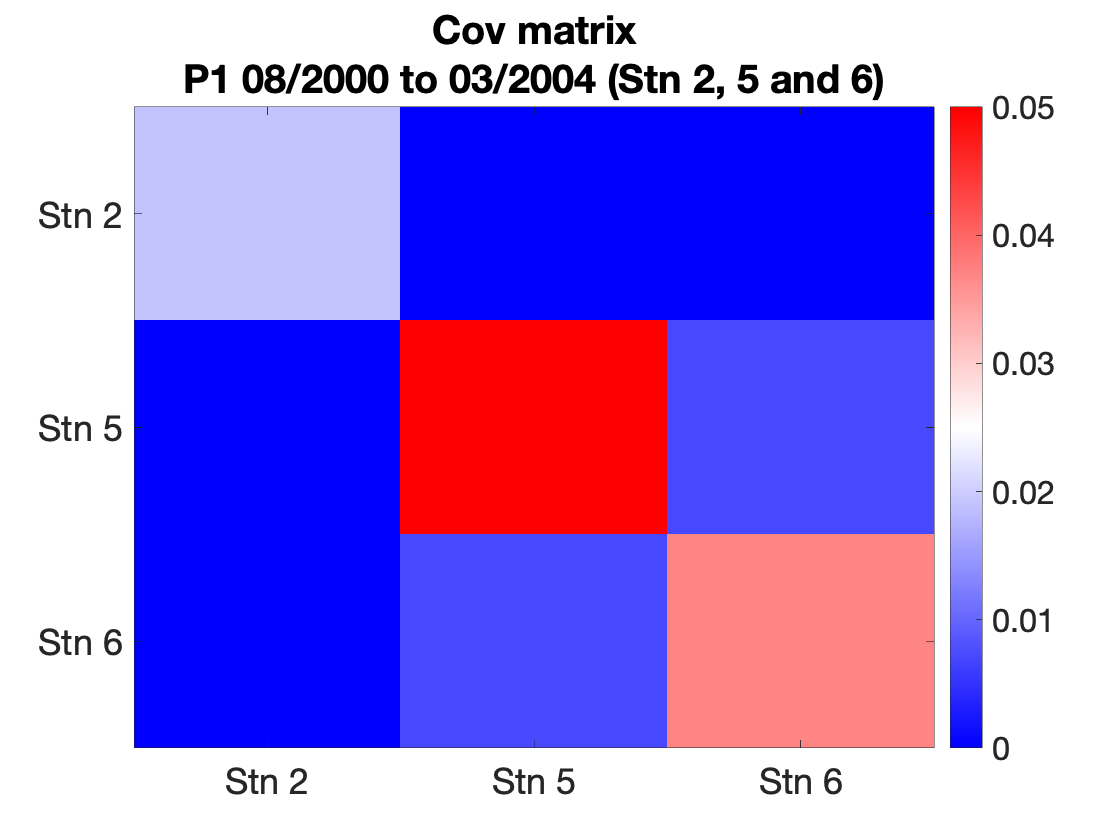

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
n=size(P1,1);
cov_p1=(P1(:,1:end-1)'*P1(:,1:end-1))/n;
figure
imagesc(cov_p1)
xticks([1 2 3])
xticklabels({'Stn 2','Stn 5','Stn 6'})
yticks([1 2 3])
yticklabels({'Stn 2','Stn 5','Stn 6'})
title({'Cov matrix'; 'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([0 .05])

#### 9) Corr Matrix

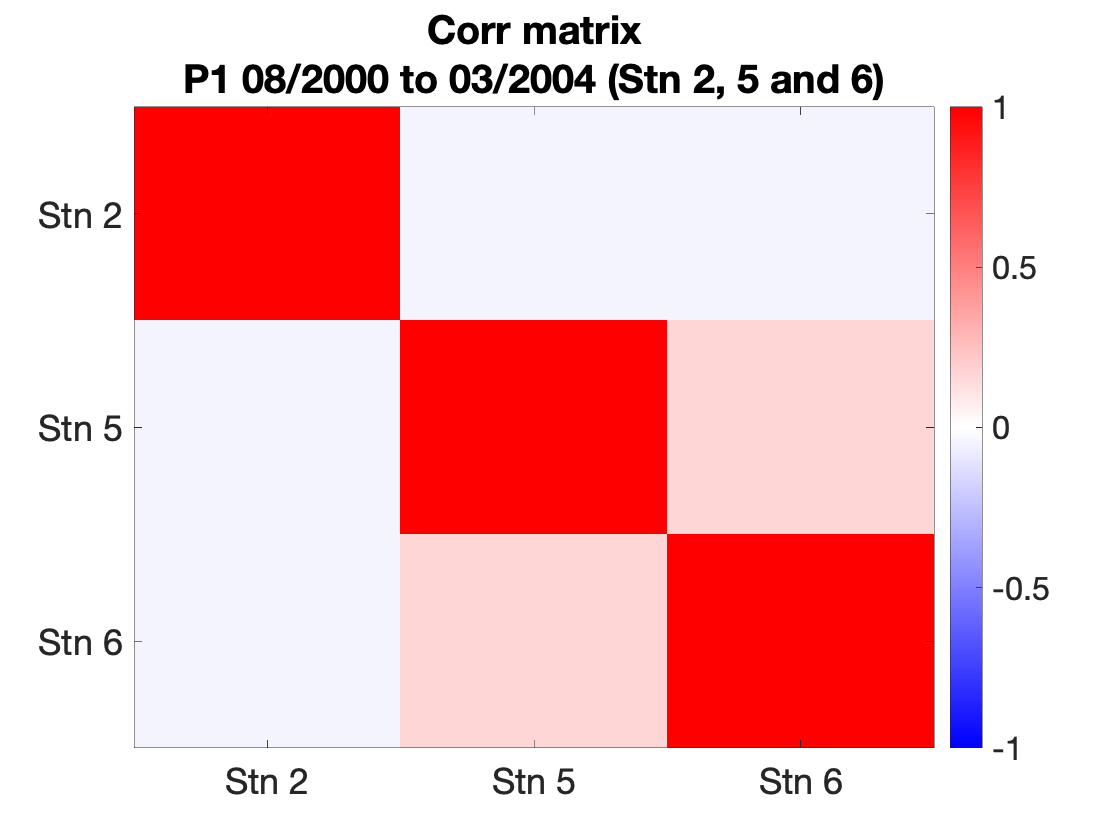

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
cor_p1=corrcov(cov_p1);
figure
imagesc(cor_p1)
xticks([1 2 3])
xticklabels({'Stn 2','Stn 5','Stn 6'})
yticks([1 2 3])
yticklabels({'Stn 2','Stn 5','Stn 6'})
title({'Corr matrix'; 'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-1 1])

#### 10)EOF/PC

%% P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
[a b]=size(P1);
P1_sqr=repmat(P1(:,1:end-1)',[1,1,b-1]);
P1_sqr=permute(P1_sqr,[1,3,2]);
[eofmap_p1,pc_p1,expv_p1] = eof(P1_sqr,9);
%Explained variance of each PC
% T_p1 = table(expv_p1(1),expv_p1(2),expv_p1(3),expv_p1(4),expv_p1(5),expv_p1(6),expv_p1(7),expv_p1(8),expv_p1(9), 'VariableNames', {'PC 1','PC 2','PC 3','PC 4','PC 5','PC 6','PC 7','PC 8','PC 9'})
T_p1 = table(expv_p1(1),expv_p1(2),expv_p1(3),expv_p1(4), 'VariableNames', {'PC 1','PC 2','PC 3','PC 4'})

T_p1 = 1×4 table
     PC 1      PC 2      PC 3        PC 4   
    ______    ______    ______    __________

    46.838    33.121    20.041    5.2382e-15


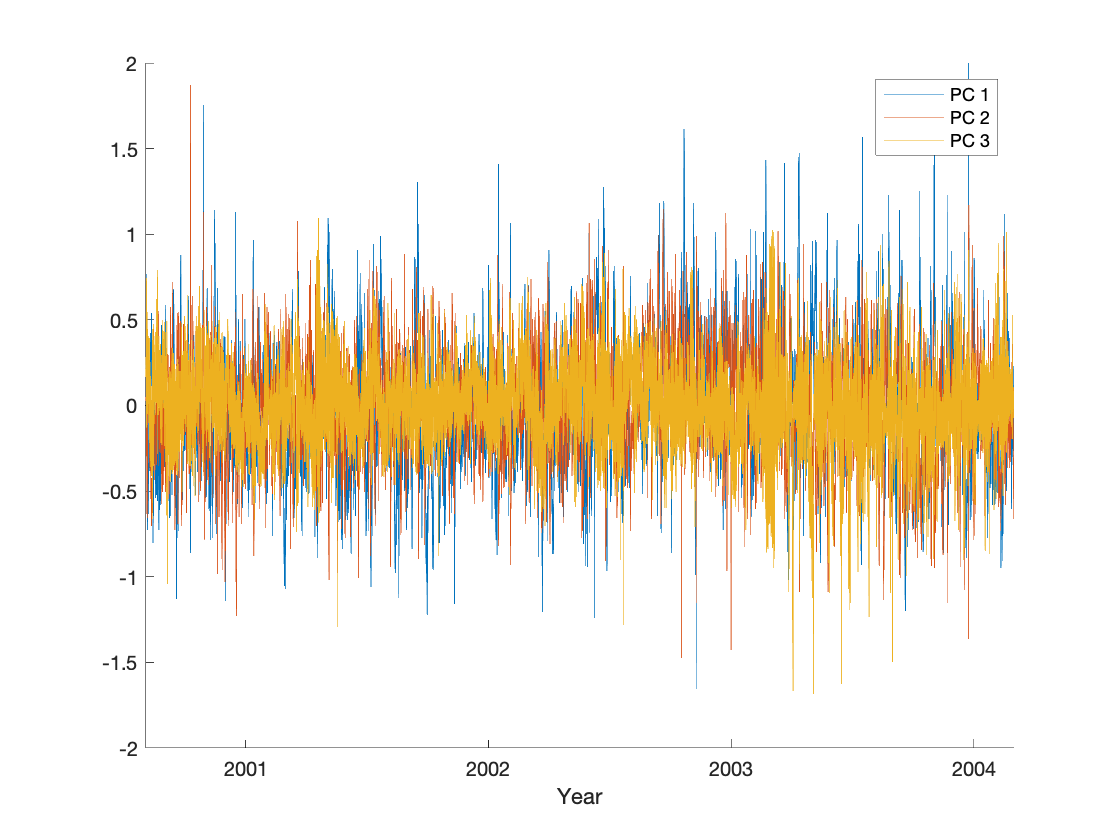

%Plot of each PC
figure
plot(P1(:,end),pc_p1(1:3,:)')
box off
axis tight
gregaxy(P1(:,end),1)
axis([P1(1,end) P1(end,end) -2 2])
% datetick('x','keeplimits')
legend('PC 1','PC 2','PC 3')

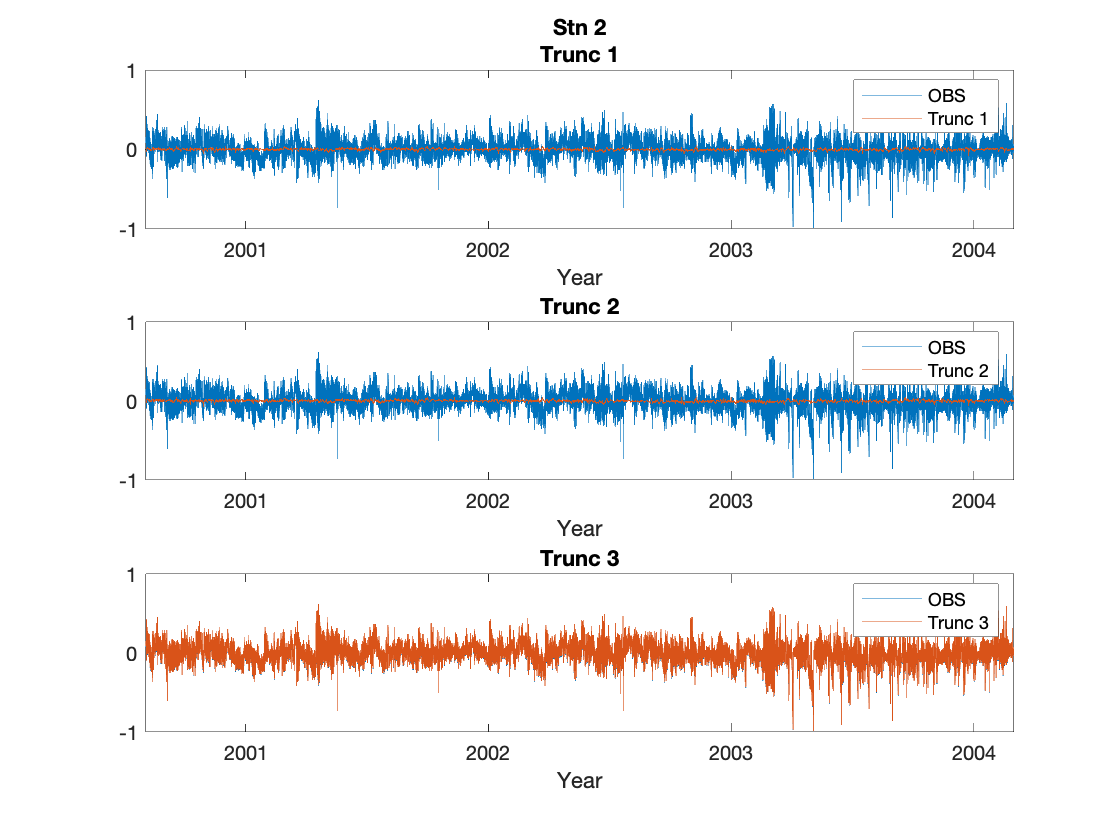

%Truncation 1, 2 and 3 (timeseries of PCs for each station)
trunc_1_p1=nan(size(P1(:,1:end-1)'));
trunc_2_p1=nan(size(P1(:,1:end-1)'));
trunc_3_p1=nan(size(P1(:,1:end-1)'));

for j=1:size(pc_p1,2)
    trunc_1_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j);      % PC1 1
    trunc_2_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j) + ... % PC1 1
                      eofmap_p1(:,1,2)*pc_p1(2,j);      % PC2 2
    trunc_3_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j) + ... % PC1 1
                      eofmap_p1(:,1,2)*pc_p1(2,j) + ... % PC2 2
                      eofmap_p1(:,1,3)*pc_p1(3,j);      % PC3 3
end        

figure
subplot(311)
plot(P1(:,end),P1(:,1)), 
hold on
plot(P1(:,end),trunc_1_p1(1,:)')
title({'Stn 2';'Trunc 1'})
gregaxy(P1(:,end),1)
legend('OBS','Trunc 1')
axis([P1(1,end) P1(end,end) -1 1])

subplot(312)
plot(P1(:,end),P1(:,1)), 
hold on
plot(P1(:,end),trunc_2_p1(1,:)')
title('Trunc 2')
gregaxy(P1(:,end),1)
legend('OBS','Trunc 2')
axis([P1(1,end) P1(end,end) -1 1])

subplot(313)
plot(P1(:,end),P1(:,1)), 
hold on
plot(P1(:,end),trunc_3_p1(1,:)')
legend('OBS','Trunc 3')
title('Trunc 3')
axis([P1(1,end) P1(end,end) -1 1])
gregaxy(P1(:,end),1)

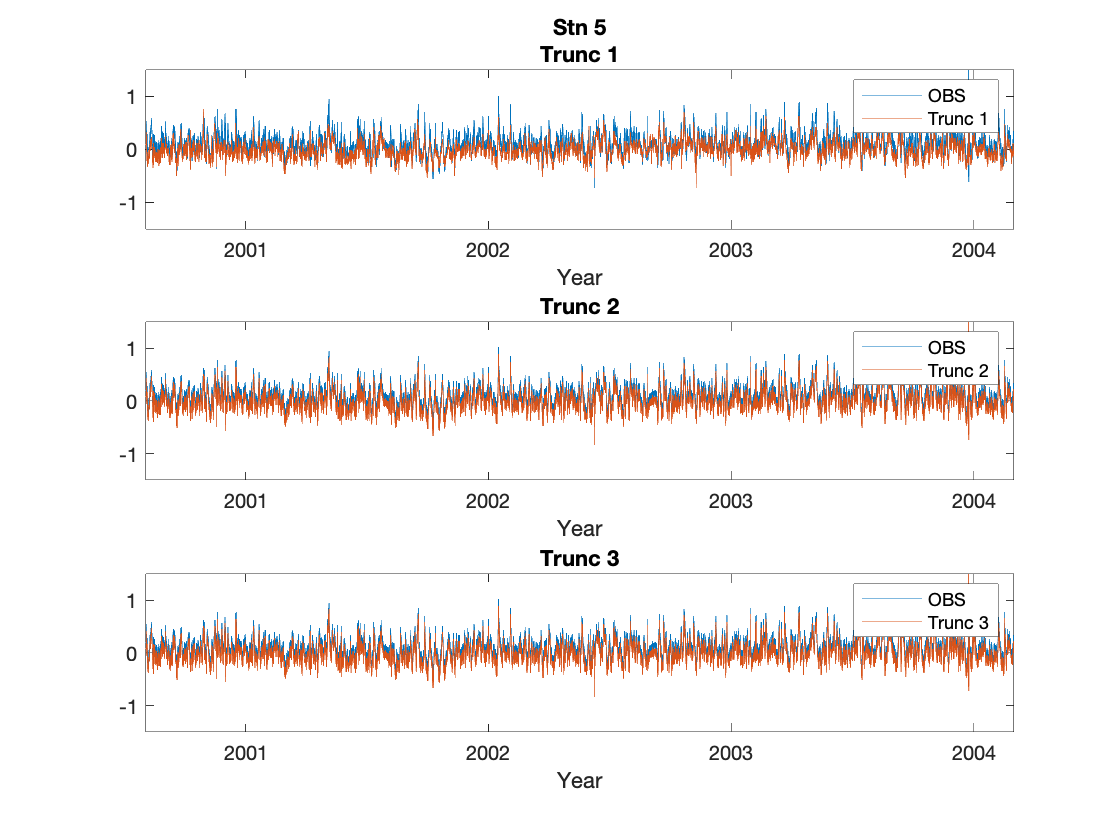

figure
subplot(311)
plot(P1(:,end),P1(:,2)), 
hold on
plot(P1(:,end),trunc_1_p1(2,:)')
legend('OBS','Trunc 1')
title({'Stn 5';'Trunc 1'})
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)

subplot(312)
plot(P1(:,end),P1(:,2)), 
hold on
plot(P1(:,end),trunc_2_p1(2,:)')
legend('OBS','Trunc 2')
title('Trunc 2')
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)

subplot(313)
plot(P1(:,end),P1(:,2)), 
hold on
plot(P1(:,end),trunc_3_p1(2,:)')
legend('OBS','Trunc 3')
title('Trunc 3')
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)

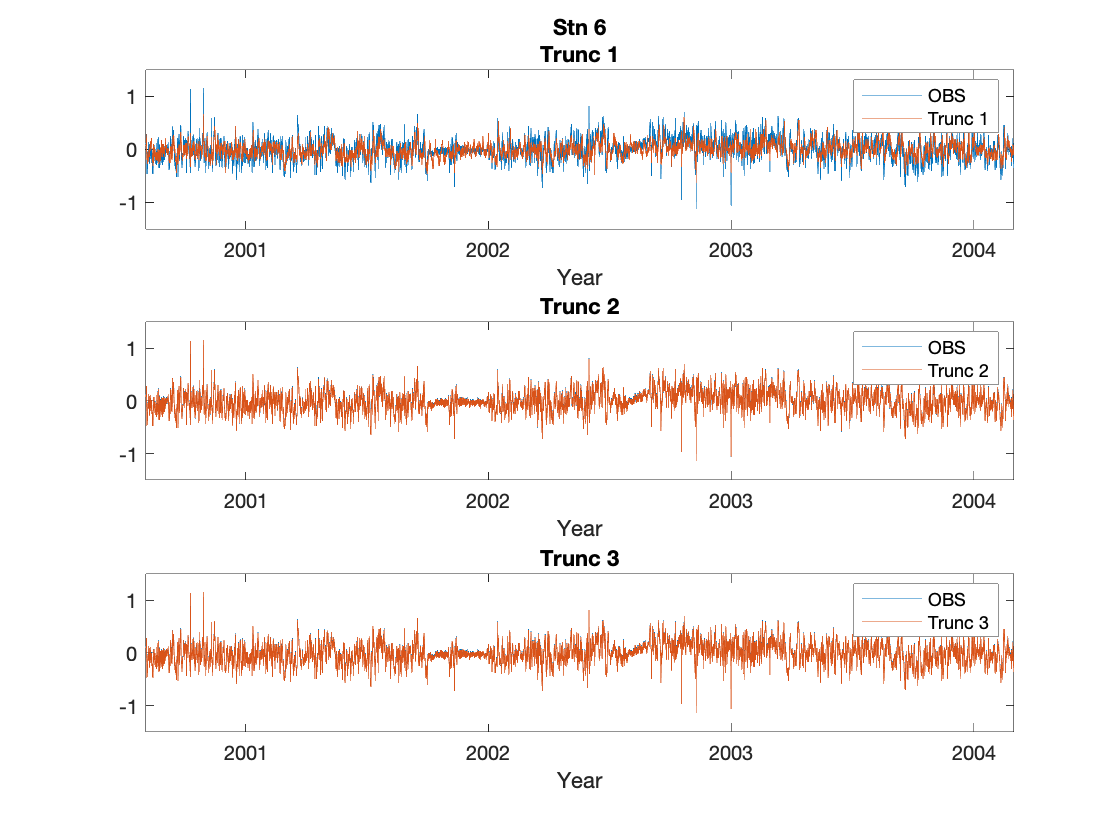

figure
subplot(311)
plot(P1(:,end),P1(:,3)), 
hold on
plot(P1(:,end),trunc_1_p1(3,:)')
legend('OBS','Trunc 1')
title({'Stn 6'; 'Trunc 1'})
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)

subplot(312)
plot(P1(:,end),P1(:,3)), 
hold on
plot(P1(:,end),trunc_2_p1(3,:)')
legend('OBS','Trunc 2')
title('Trunc 2')
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)

subplot(313)
plot(P1(:,end),P1(:,3)), 
hold on
plot(P1(:,end),trunc_3_p1(3,:)')
legend('OBS','Trunc 3')
title('Trunc 3')
axis([P1(1,end) P1(end,end) -1.5 1.5])
gregaxy(P1(:,end),1)